# **Lab 5**

**Part 1**

In this part of the lab we are trying to see the differences between the random qcd events and the events attributed to the Higgs boson. There are a total of 14 variables that can be extracted from the information and in this part of the lab we are going to compare different variable distributions for both qcd and Higgs data and see if there are significant differences in their behavior. 

Here is the picture of the structure of ATLAS detector from [https://hep.uchicago.edu/~johnda/thesis/Atlas.pdf](https://hep.uchicago.edu/~johnda/thesis/Atlas.pdf)

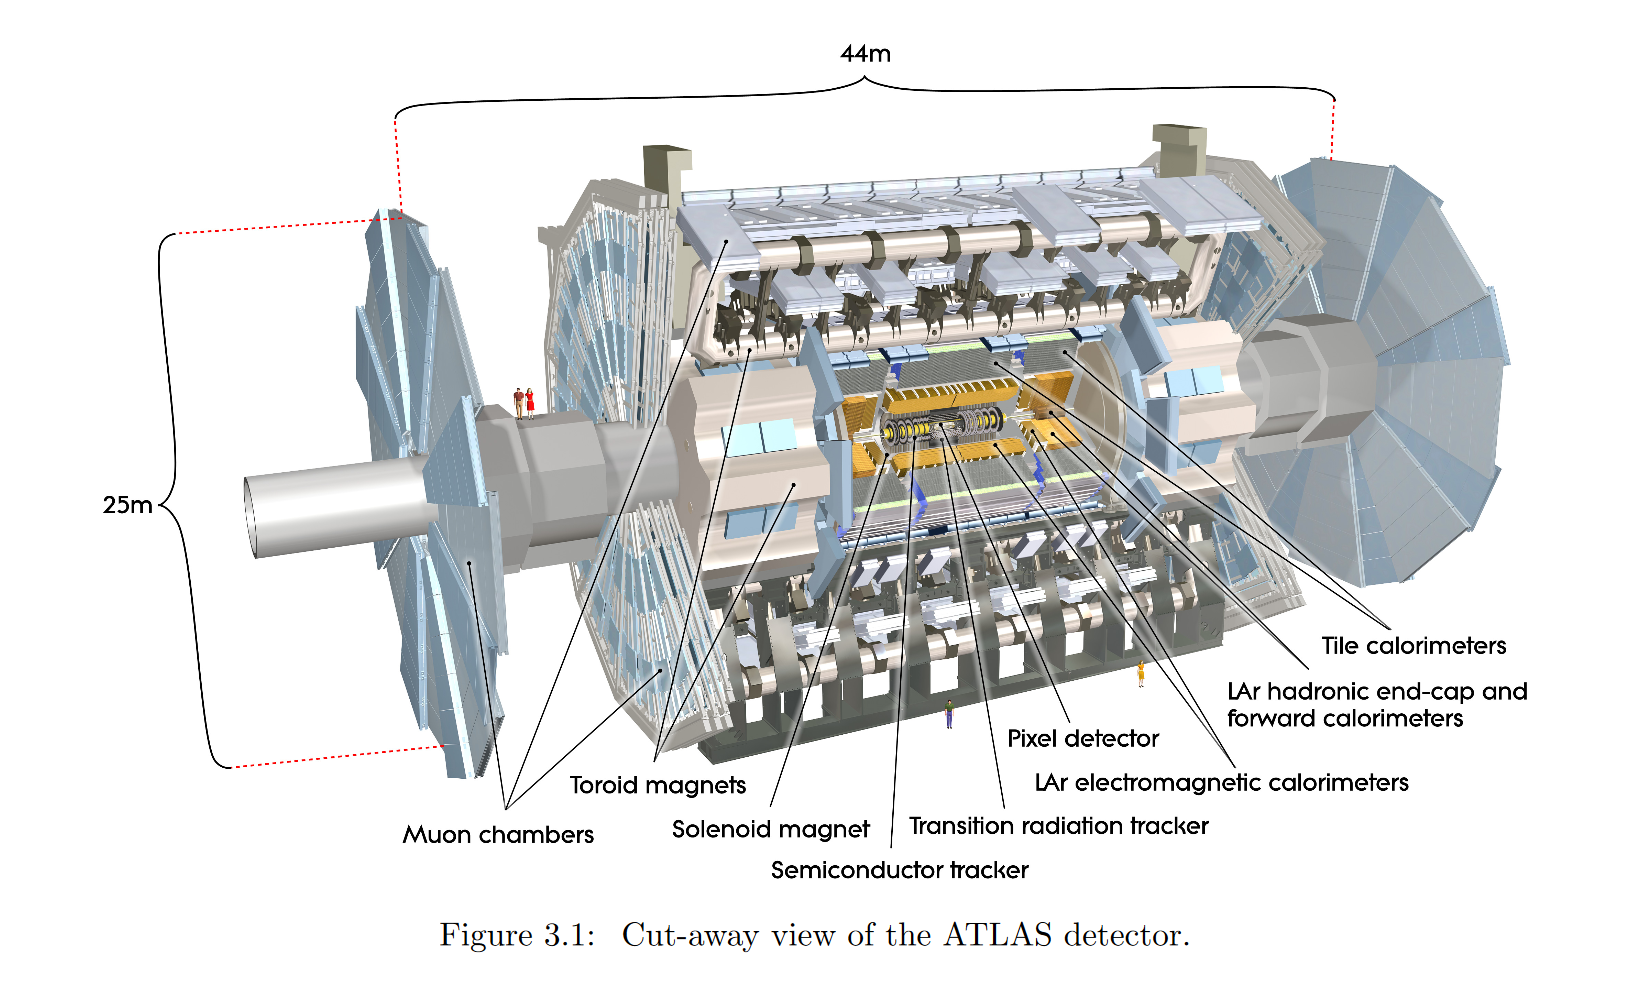

In each graph, the** pink **corresponds to Higgs data, and **blue** to qcd data.

Import the data:

clc; close all; clear all;
h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgData = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcdData = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

Compare **transverse momentum (pt)**, the first variable. Transverse momentum is the momentum of the interacting particles involved in the event where non-transverse momentum is the one associated with the non-interacting particles involved in the event. 

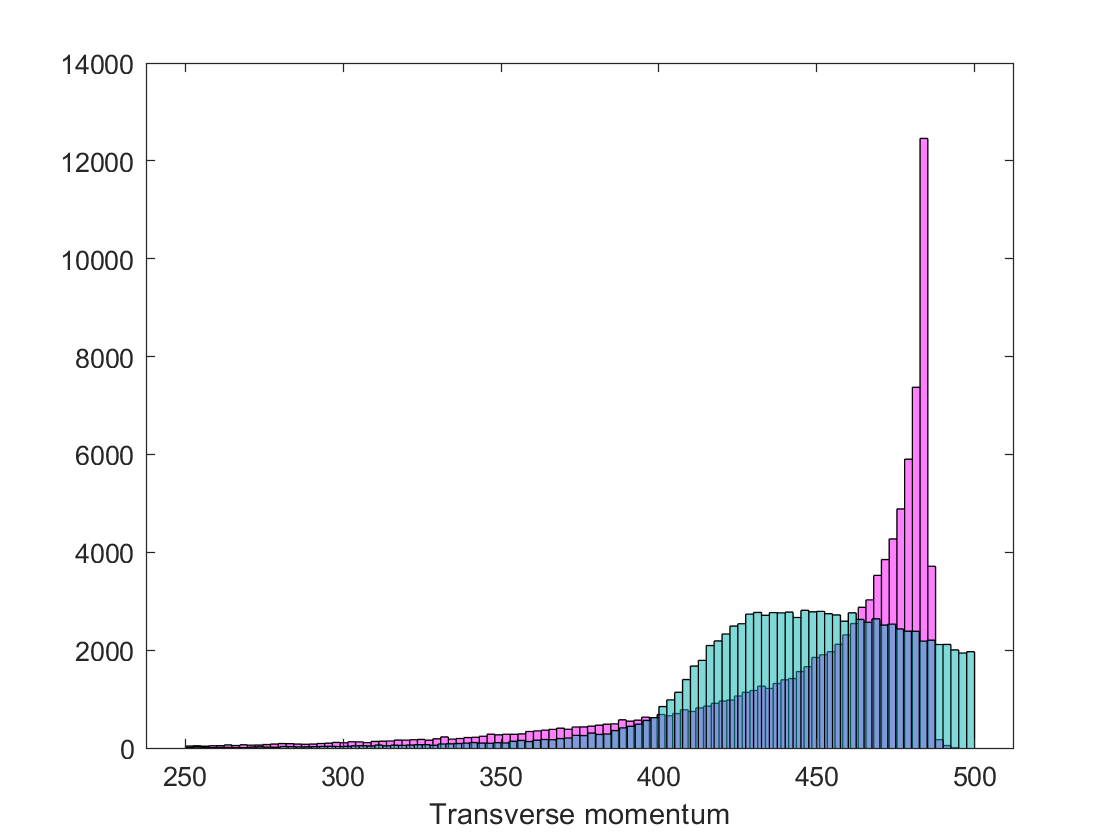

hTransverseMomentum = higgData(1,:);
histogram(hTransverseMomentum,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Transverse momentum'
hold on
qcdTransverseMomentum = qcdData(1,:);
histogram(qcdTransverseMomentum,100, 'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

From the graph, while the transverse momentum of an average qcd event is in the same range as the events associated with Higgs there is a big spike for the Higgs distribution at large transverse momentum. However, a significant portion of qcd events have high values of transverse momentum too so we cannot say with a high degree of certainty that an event with a high transverse momentum is an appearance of Higgs.

Compare **pseudorapidity, **which is the measurement of the angle between the particle and the beam axis. Events with low pseudorapidity are registered, while the events with higher pesudorapidity are generally lost.

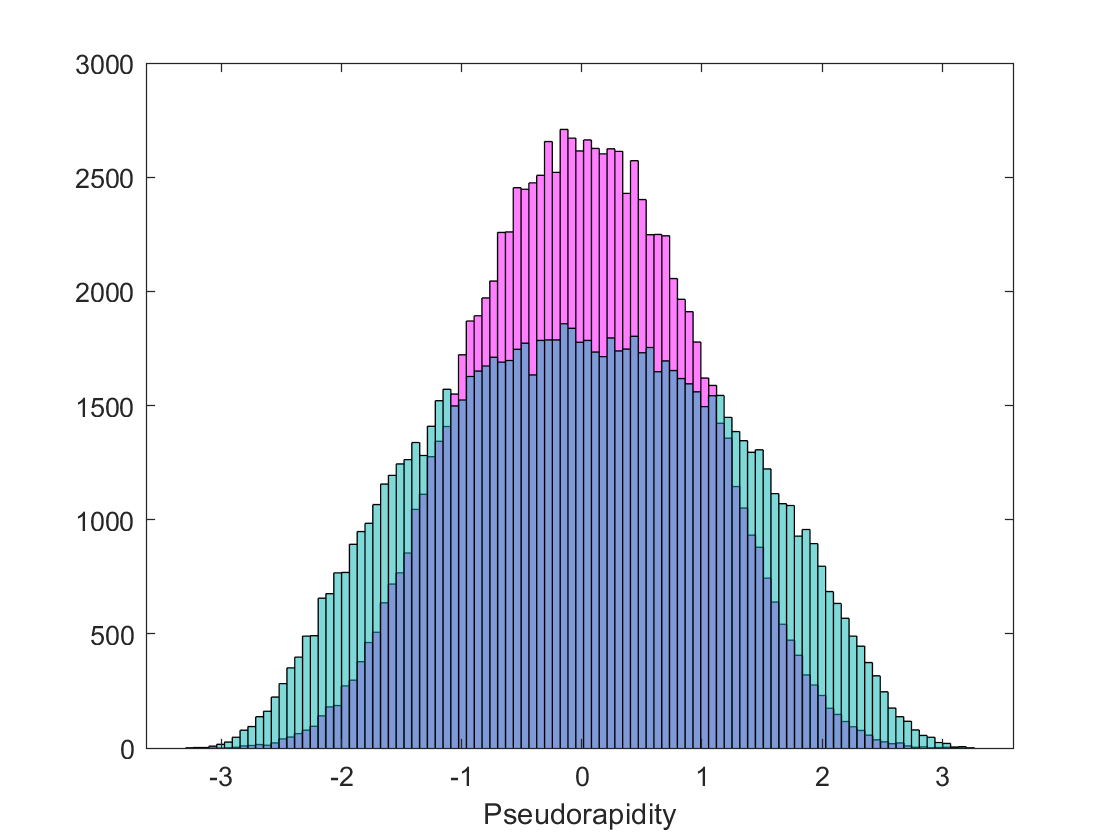

hPseudorapidity = higgData(2,:);
histogram(hPseudorapidity,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Pseudorapidity'
hold on
qcdPseudorapidity = qcdData(2,:);
histogram(qcdPseudorapidity,100, 'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

While Higgs data has a smaller standard deviation, it would be hard to differentiate between it and qcd pseudorapidity since they have the same mean and overlap in most cases.

Compare **azimuthal angle, **the measure of the angle from the x-axis around the beam.

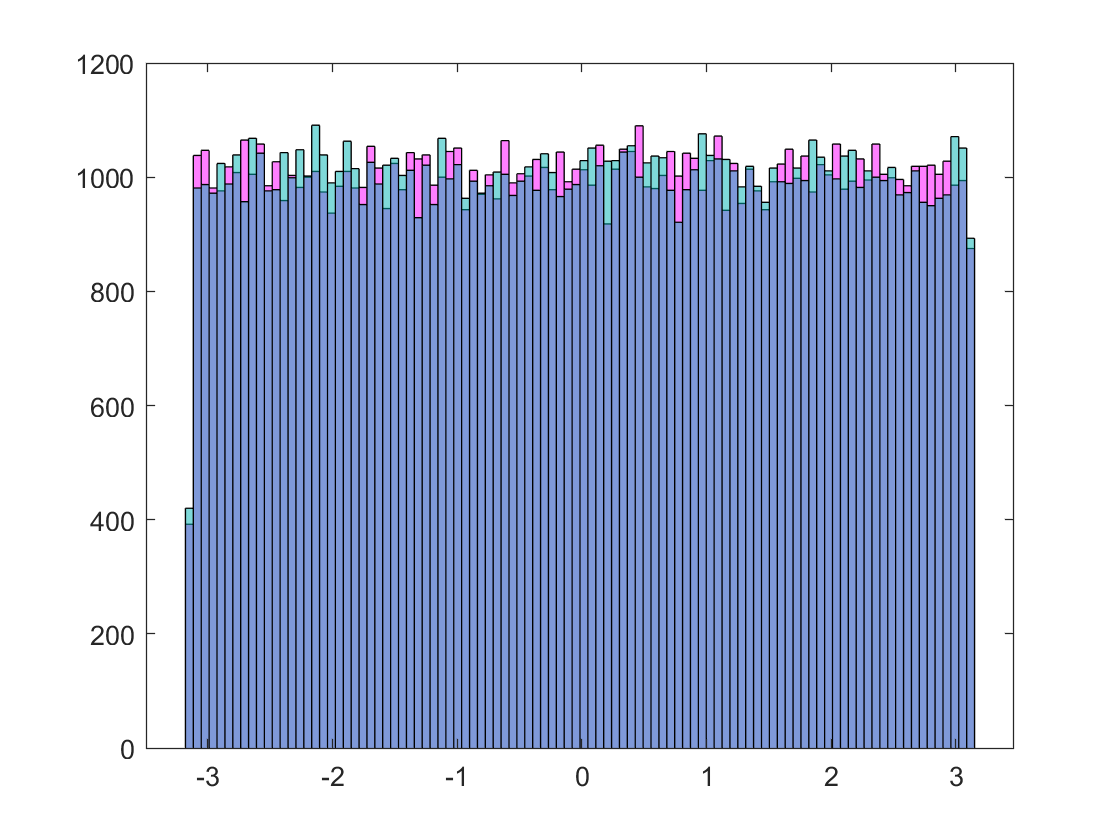

hAzimuthalAngle = higgData(3,:);
histogram(hAzimuthalAngle,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
hold on
qcdAzimuthalAngle = qcdData(3,:);
histogram(qcdAzimuthalAngle,100, 'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

It seems that there no either trends nor significant distinctions between the measures of qcd and Higgs azimuthal angle.

Compare** invariant masses,** 

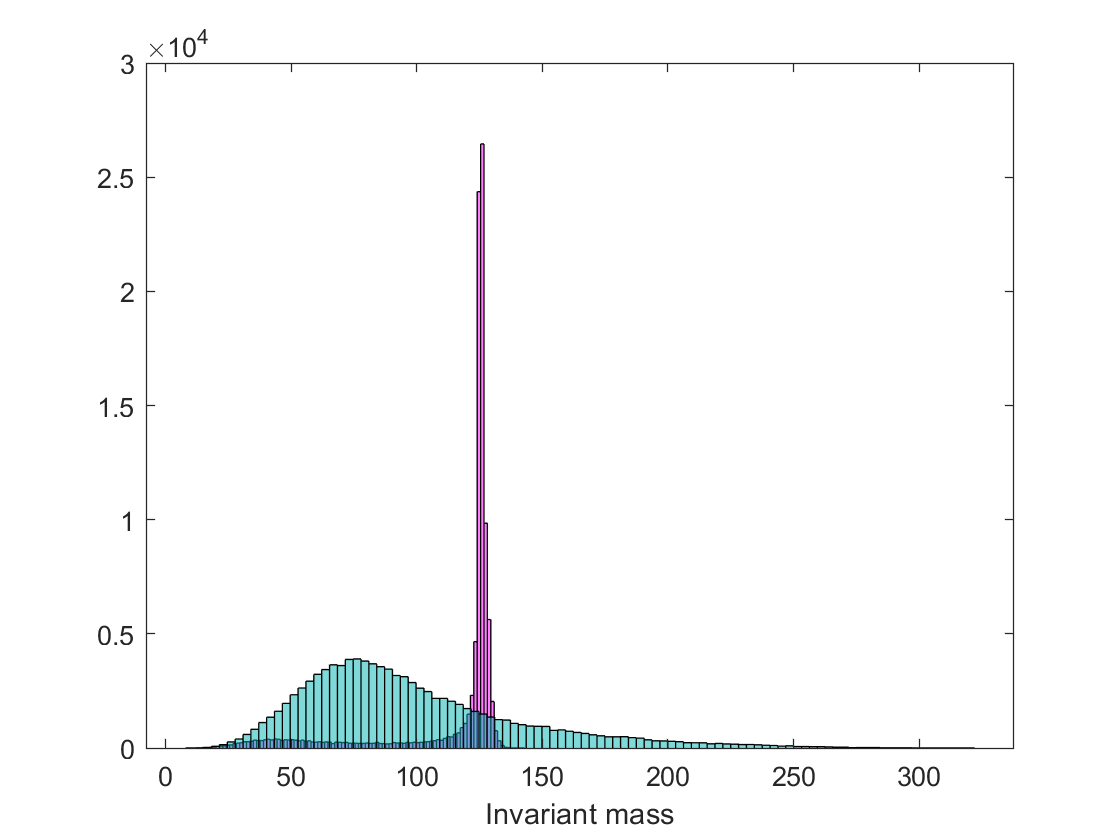

hInvariantMass = higgData(4,:);
histogram(hInvariantMass,100,'FaceColor',[1,0,1],'FaceAlpha',0.5);
xlabel 'Invariant mass'
hold on
qcdInvariantMass = qcdData(4,:);
histogram(qcdInvariantMass,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5);
hold off

There is a spike of Higgs values in mass [120 132] range. I found all the indexes of the qcd data that correspond to the mass range similar to Higgs. It might be useful to see if that mass range of qcd has different characteristics from other qcd data points.

higgsMassMean = mean(hInvariantMass)

higgsMassMean = 114.8924

higgsStandardDeviation = std(hInvariantMass)

higgsStandardDeviation = 25.3511

Sigma is large and skewed because of the low mass Higgs data so a range that's proportional to sigma can't be used.

If we were to only use the range of the spike then the values that are most present in higgs mass data are within [120 132] range. We now collect the indices of QCD data points that have mass within the range of that spike.

newIndex(1)=0;
newLength=1;
for i = 1:length(qcdInvariantMass)
    if (qcdInvariantMass(i) > 120 && qcdInvariantMass(i) < 132)
            newIndex(newLength) = i;
            newLength = newLength+1;
    end
end
newIndex;
newQCDInvariantMass = qcdInvariantMass(newIndex)

newQCDInvariantMass =   125.2987  129.7314  126.6088  120.2214  123.2770  130.3697  131.0429  127.8190  123.0123  130.3911  130.6138  130.3051  131.8322  129.8032  124.6375  123.3230  126.5294  120.8553  126.9798  131.1310  125.7437  121.9188  124.9882  124.7957  124.9622  121.1549  123.2505  128.7236  121.0058  122.5745  126.7850  124.2862  127.8086  122.0669  122.0243  120.0297  130.2557  121.2242  131.2107  126.8021  125.1040  130.9671  122.4575  126.9004  120.1395  124.0442  127.0033  127.3005  124.1091  128.4695


Compare **2 point ECF ratio, **being energy correlation ratio.

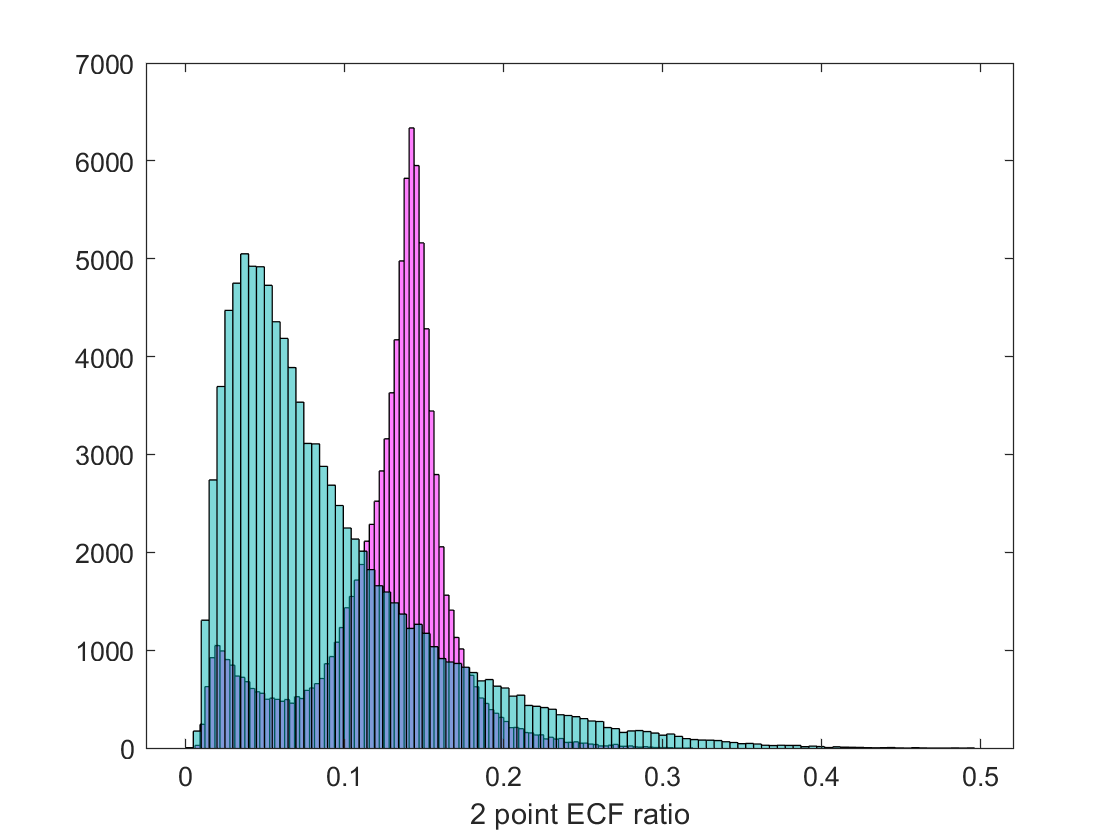

hee2 = higgData(5,:);
histogram(hee2,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel '2 point ECF ratio'
hold on
qcdee2 = qcdData(5,:);
histogram(qcdee2,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

The 2 point ECF ratio attributed to the Higgs data has a higher mean, but there is still a significant overlap between both sets of data. Also while qcd 2 point ECF ratio follows a Poisson distribution with a median of 0.03, the Higgs data has a big spike around 0.17 and a small one around 0.02.

Compare **3 point ECF ratio, **being energy correlation ratio.

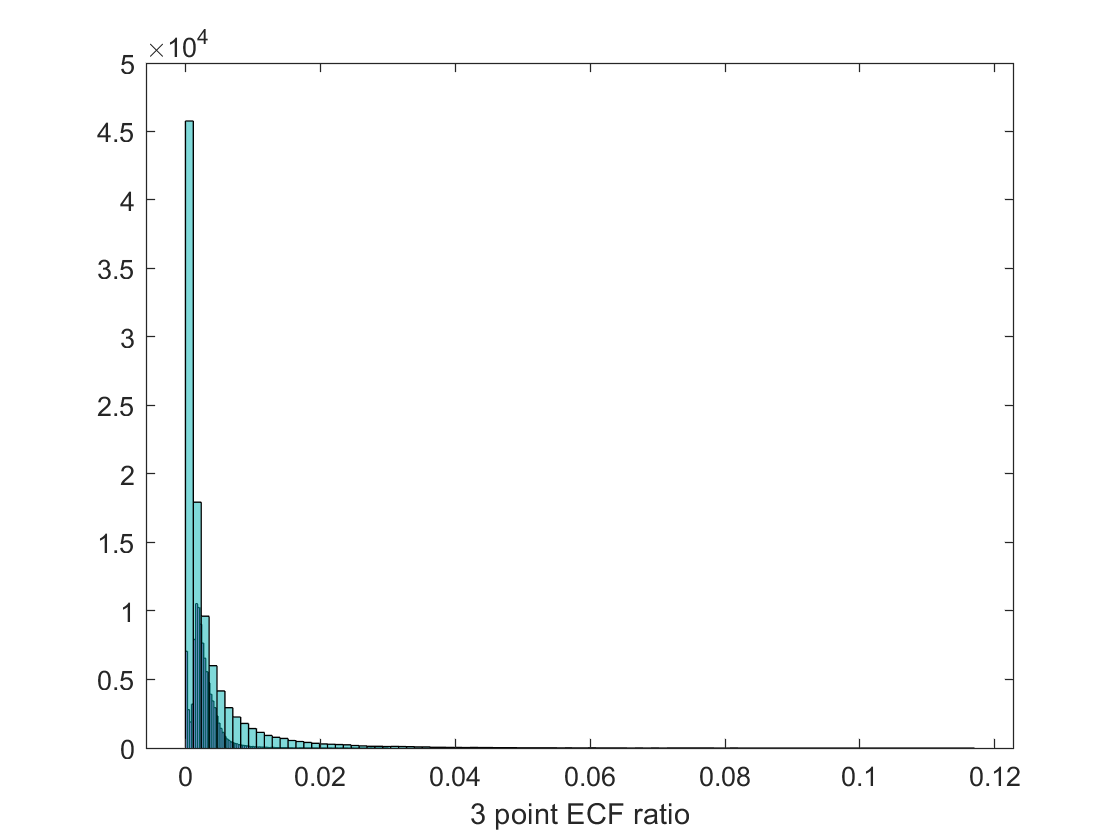

hee3 = higgData(6,:);
histogram(hee3,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel '3 point ECF ratio'
hold on
qcdee3 = qcdData(6,:);
histogram(qcdee3,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Both distributions look Poisson, with a significant overlap in values. 

Compare **3 to 2 point ECF ratio. **

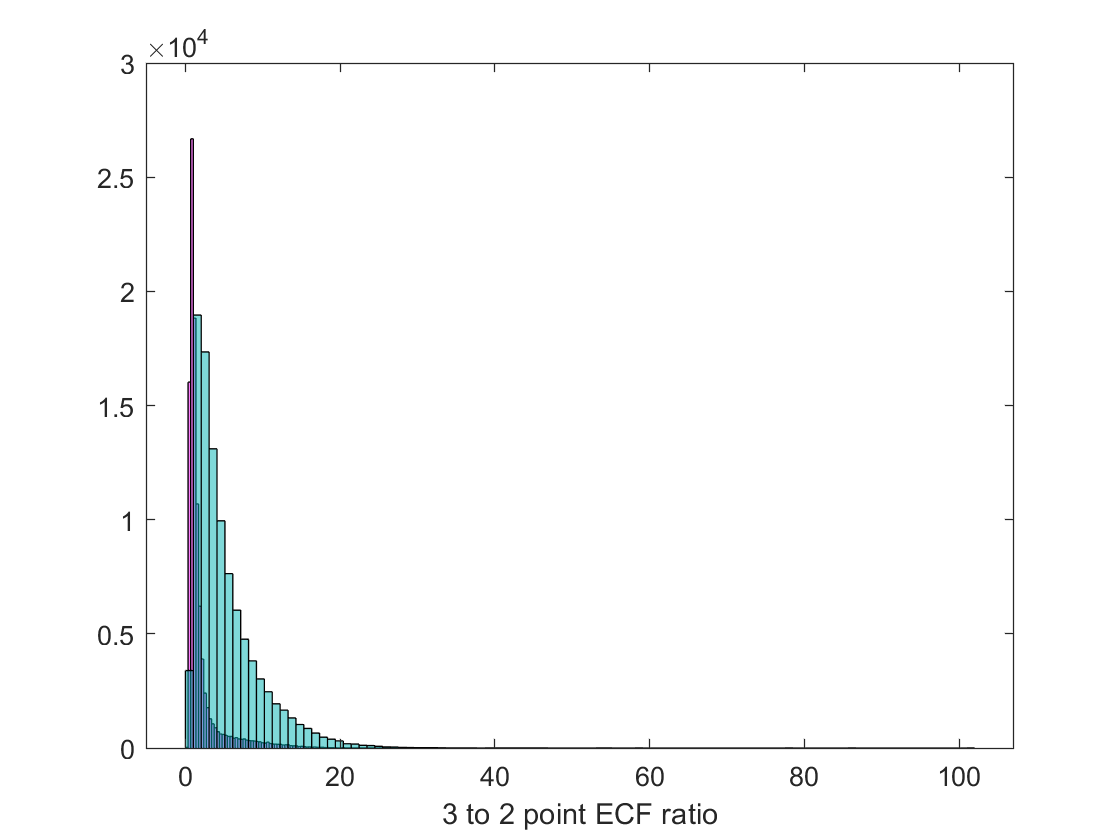

hd2 = higgData(7,:);
histogram(hd2,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel '3 to 2 point ECF ratio'
hold on
qcdhd2 = qcdData(7,:);
histogram(qcdhd2,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Both distributions look Poisson, with a significant overlap in values. The Higgs 32ecf has a lower mean and a smaller deviation.

Compare **angularity.**

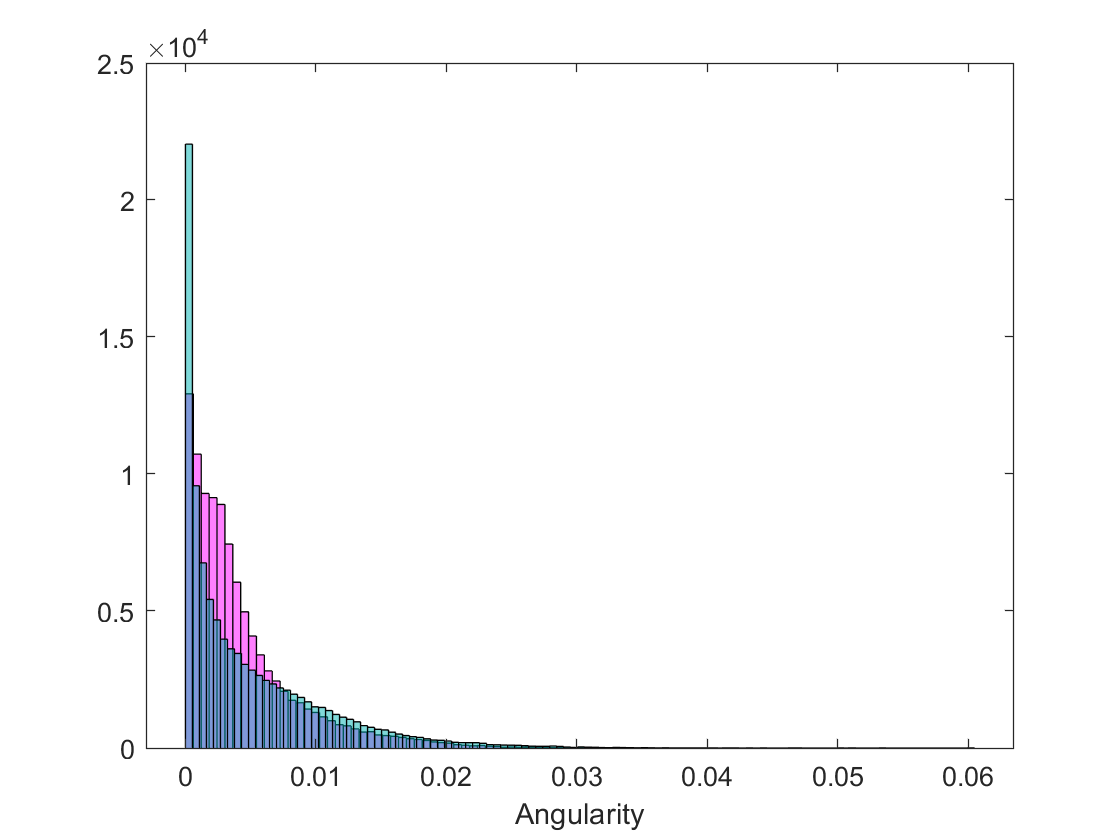

hAngularity = higgData(8,:);
histogram(hAngularity,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Angularity'
hold on
qcdAngularity = qcdData(8,:);
histogram(qcdAngularity,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Higgs angularity is more spread out, but the distributions overlap significantly as well.

Compare **variable 9 **

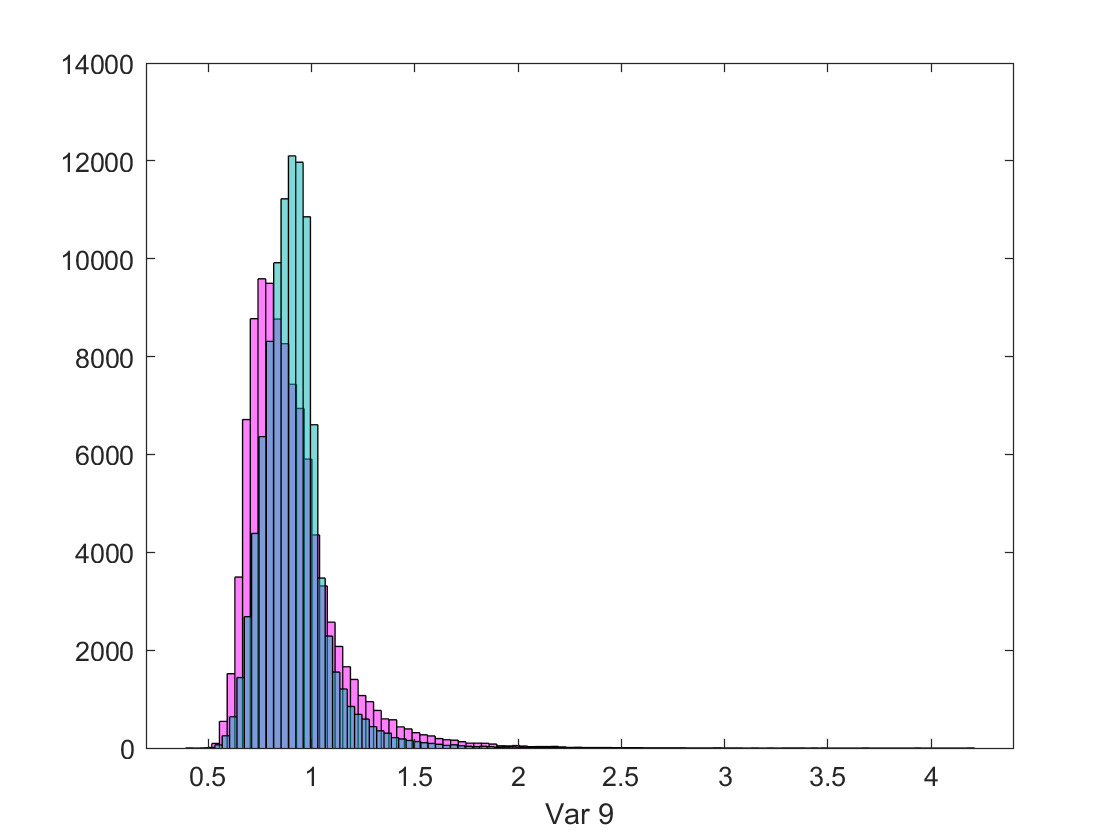

hvar9 = higgData(9,:);
histogram(hvar9,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 9'
hold on
qcdvar9 = qcdData(9,:);
histogram(qcdvar9,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

While the median values are slightly different, the two sets of data seem to share similar characteristics of the variable 9. 

Compare **variable 10**

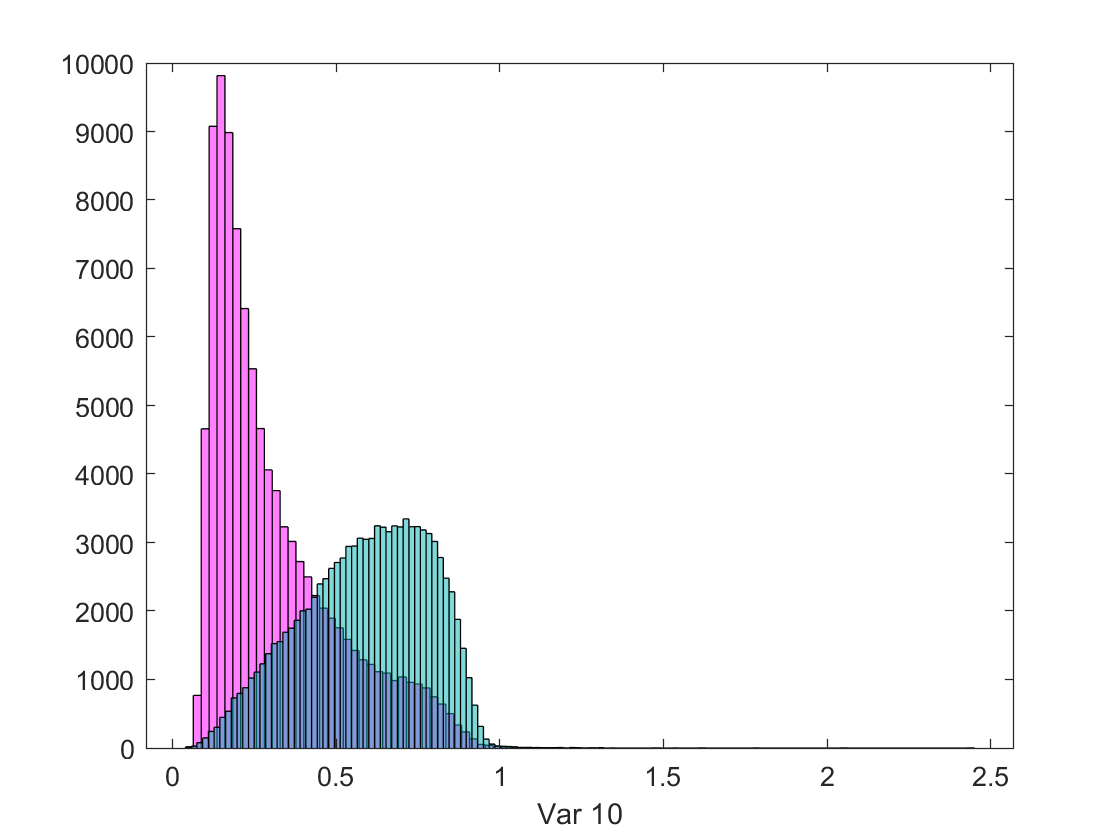

hvar10 = higgData(10,:);
histogram(hvar10,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 10'
hold on
qcdvar10 = qcdData(10,:);
histogram(qcdvar10,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Higgs variable 10 is Poisson distributed with a much smaller median than qcd. However, the median value while being in the region of 4-5 sigma of qcd variable 10, it is on the verge of being significant or not.

Compare **variable 11**

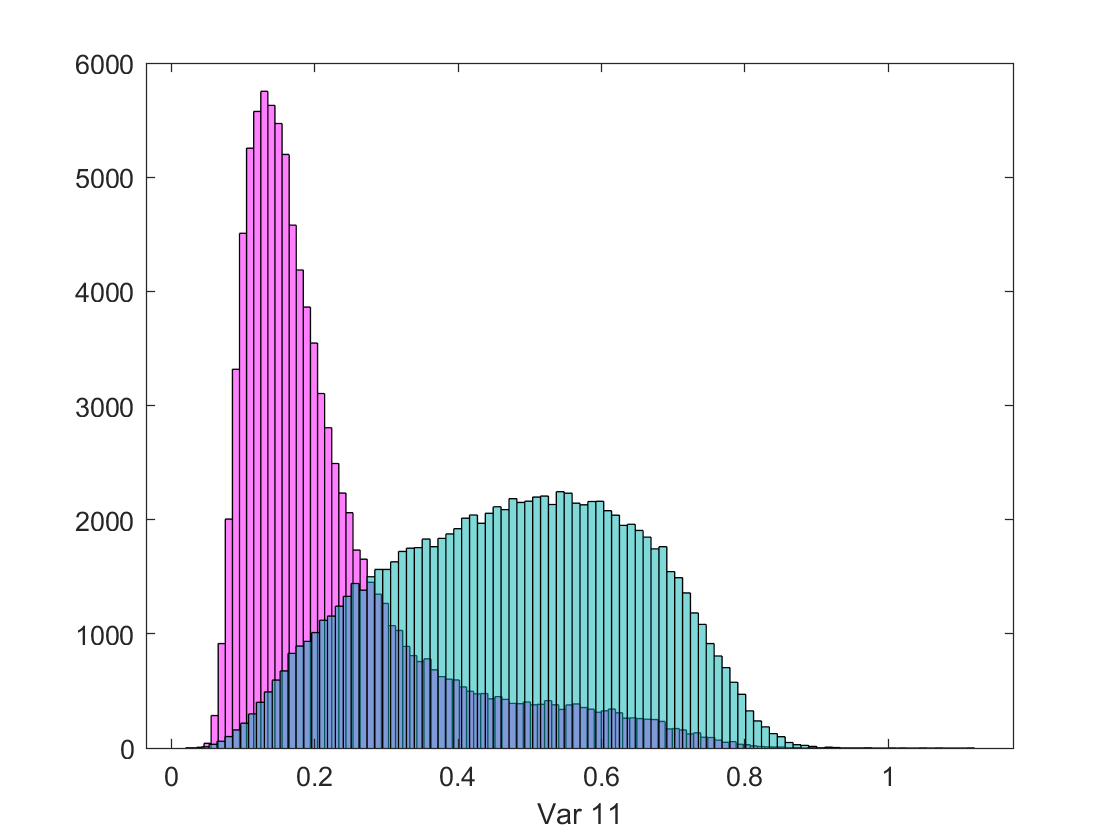

hvar11 = higgData(11,:);
histogram(hvar11,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 11'
hold on
qcdvar11 = qcdData(11,:);
histogram(qcdvar11,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Compare **variable 12**

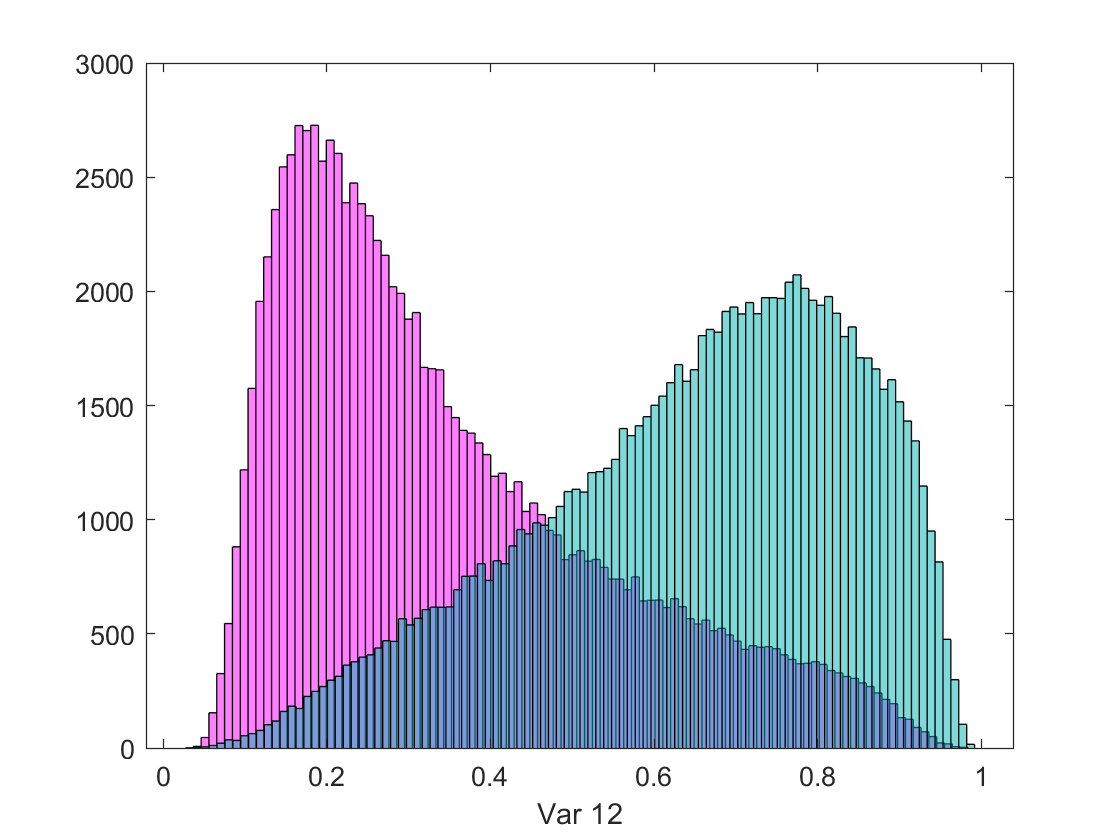

hvar12 = higgData(12,:);
histogram(hvar12,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 12'
hold on
qcdvar12 = qcdData(12,:);
histogram(qcdvar12,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Compare **variable 13**

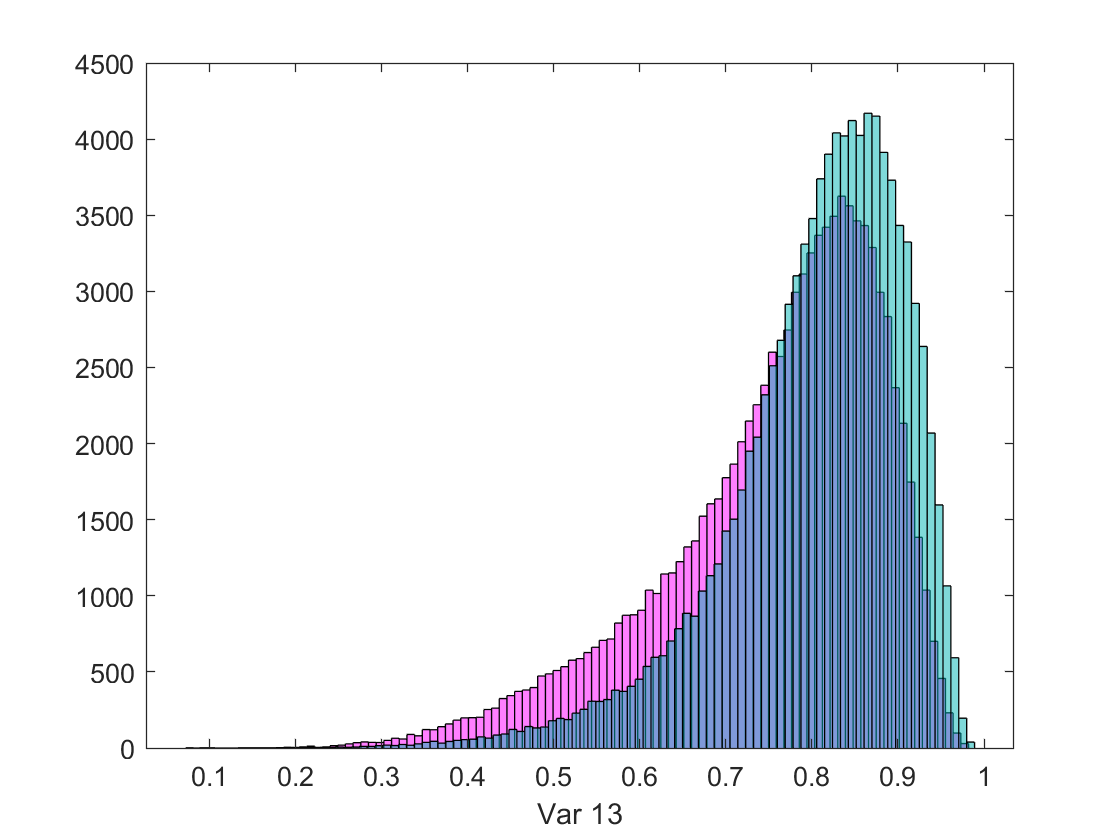

hvar13 = higgData(13,:);
histogram(hvar13,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 13'
hold on
qcdvar13 = qcdData(13,:);
histogram(qcdvar13,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

Variables 11,12, and 13 share similarities, where both distributions range [0 1] but Higgs data's median is around 0.2 for 11 and 12, and median for qcd is 0.55 for 11, 0.75 for 12. These variables could potentially be used to discern between qcd and Higgs. 

Variable 13, in contrast, is almost the exact same for both qcd and Higgs.

Compare **variable 14**

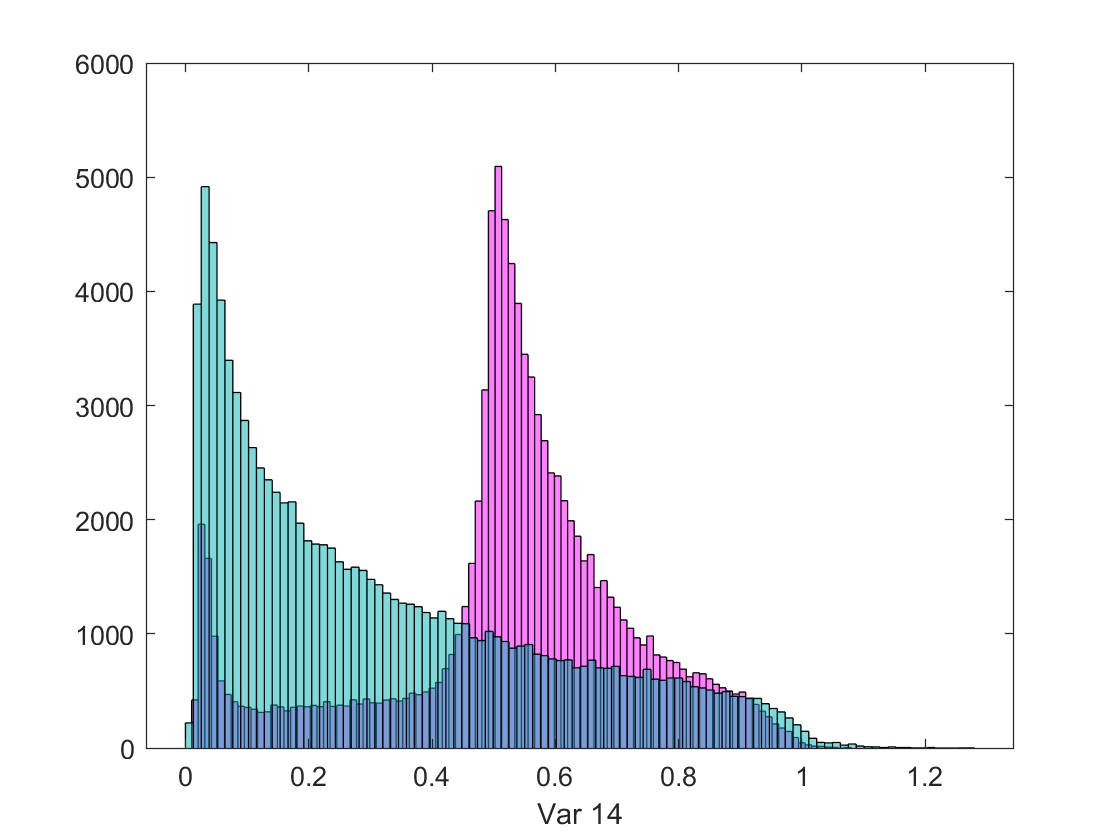

hvar14 = higgData(14,:);
histogram(hvar14,100,'FaceColor',[1,0,1],'FaceAlpha',0.5)
xlabel 'Var 14'
hold on
qcdvar14 = qcdData(14,:);
histogram(qcdvar14,100,'FaceColor',[0,0.7,0.7],'FaceAlpha',0.5)
hold off

The Higgs distribution has a spike at 0.55 while the qcd distribution has a spike around 0.05. However, both of these distributions are spread across a similar range of values so while this variable could be useful for discerning the two, it should be taken with a degree of caution.

In conclusion, the data presented offers a lot of possibilities for exploration and work.